clc; clear; close all;

## Get Audio Signal from .wav for input of testbench

%% Generate Audio Information Signal
[audio, fs_orig] = audioread('input.wav');
audio = mean(audio, 2);
audio = resample(audio, 48000, fs_orig);
audio = audio / max(abs(audio));

## Parameters for FM Radio

%% Parameter for FM signal processing
fs_rf = 1.92e6;         % sampling rate for baseband IQ samples
fs_audio = 48000;       % sampling rate for audio signal
freq_dev = 75e3;        % frequency deviation
tau = 75e-6;
tau2 = tau / 10; 

%% Parameter for FIR Decimator
% Channel LPF + 5:1 Decimation (1.92M → 384k)
decim1 = 5;
f1 = [0 (154e3/(fs_rf/2)) (230e3/(fs_rf/2)) 1];
A1 = [1 1 0 0];
CoefFilter1 = firpm(48,f1,A1);
fs_if1 = fs_rf / decim1;  % 384 kHz

% Anti-Aliasing LPF + 2:1 Decimation (384k → 192k)
decim2 = 2;
f2 = [0 (72e3/(fs_if1/2)) (120e3/(fs_if1/2)) 1];
A2 = [1 1 0 0];
CoefFilter2 = firpm(15,f2,A2);
fs_if2 = fs_if1 / decim2; % 192 kHz

% Anti-Aliasing LPF + 2:1 Decimation (192k → 96k)
decim3 = 2;
f3 = [0 (24e3/(fs_if2/2)) (72e3/(fs_if2/2)) 1];
A3 = [1 1 0 0];
CoefFilter3 = firpm(11,f3,A3);
fs_if3 = fs_if2 / decim3; % 96 kHz

% Anti-Aliasing LPF + 2:1 Decimation (96k → 48k)
decim4 = 2;
f4 = [0 (20e3/(fs_if3/2)) (28e3/(fs_if3/2)) 1];
A4 = [1 1 0 0];
CoefFilter4 = firpm(35,f4,A4);
fs_if4 = fs_if3 / decim4; % 48 kHz

%%  If you want to check frequency response for filter, then use this command.
% filterAnalyzer(CoefFilter1,FilterNames=["Filter1"], MagnitudeMode="db")

%% De-emphasis IIR Filter: H(s) = (tau2*s + 1) / (tau*s + 1)
[b_de, a_de] = bilinear([tau2 1], [tau 1], fs_audio);

## Modulate Audio Signal and Transmit

%% Pre-emphasis: H(s) = (tau*s + 1) / (tau2*s + 1), tau2 < tau
[b_pe, a_pe] = bilinear([tau 1], [tau2 1], fs_audio);
audio_pe = filter(b_pe, a_pe, audio);

%% Interpolating audio signal for Baseband IQ sampling rate
audio_up = resample(audio_pe, fs_rf, fs_audio);  % 48k → 1.92M (40x)

%% FM modulation and generate baseband IQ samples.
phase = cumsum(2*pi * freq_dev / fs_rf * audio_up);
tx_iq = exp(1j * phase);

## Add Channel Properties during Trasmission

%% Rayleigh 다중경로
ch = comm.RayleighChannel('SampleRate', fs_rf, ...
    'PathDelays', [0 1e-6 3e-6], ...
    'AveragePathGains', [0 -3 -6], ...
    'MaximumDopplerShift', 5);
rx_faded = ch(tx_iq);

%% AWGN
SNR_dB = 10;
rx_iq = awgn(rx_faded, SNR_dB, 'measured');

## Golden reference with MATLAB Script

%% Channel LPF
filtered_iq = filter(CoefFilter1, 1, rx_iq);
filtered_iq = filtered_iq(1:decim1:end);

%% Cross-Multiply Discriminator
dphi = angle(filtered_iq(2:end) .* conj(filtered_iq(1:end-1)));

%% Anti-Aliasing LPF
filtered_audio = filter(CoefFilter2, 1, dphi);
filtered_audio = filtered_audio(1:decim2:end);

filtered_audio = filter(CoefFilter3, 1, filtered_audio);
filtered_audio = filtered_audio(1:decim2:end);

filtered_audio = filter(CoefFilter4, 1, filtered_audio);
filtered_audio = filtered_audio(1:decim2:end);

%% De-emphasis IIR Filter
audio_out_gd = filter(b_de, a_de, filtered_audio);

## Our DUT in Simulink

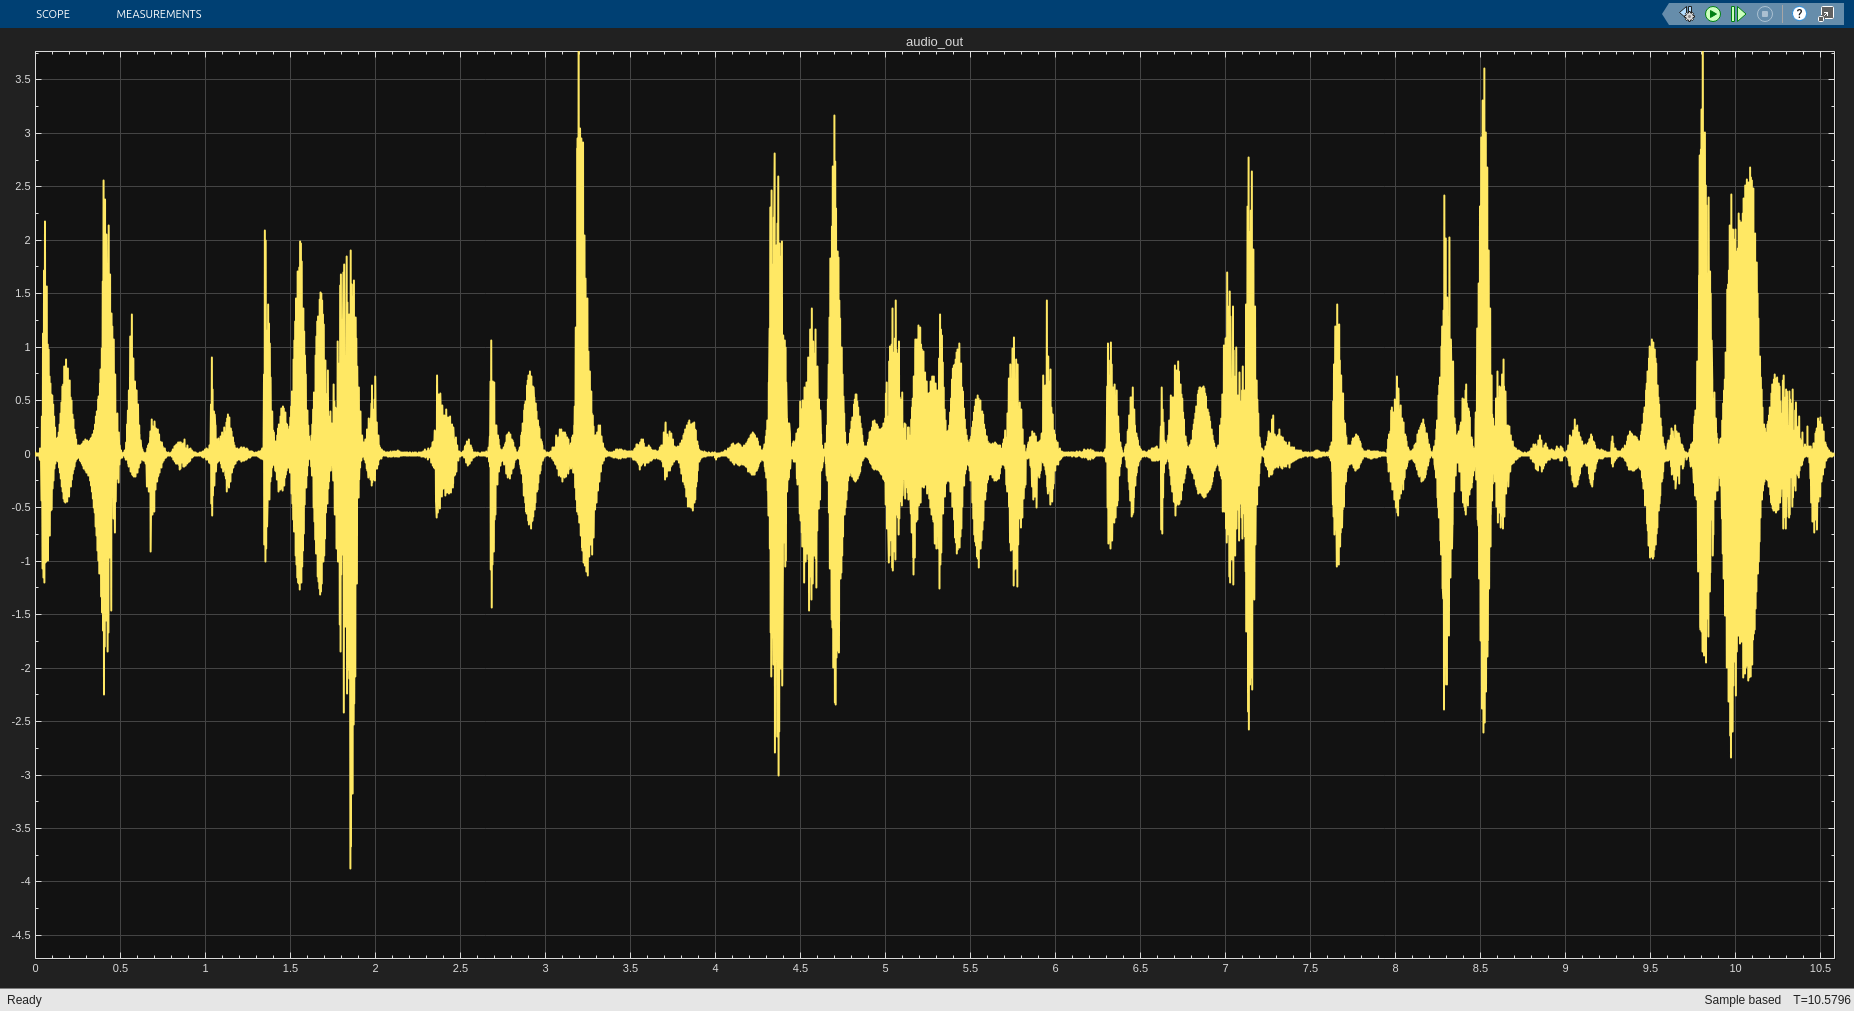

%% Simulation Time for Simulink
SimTime = length(rx_iq);
SimTime = SimTime / fs_rf;

%% Run Simulink
slout = sim("fm_radio_simulink_v1.slx");


%% Get Log from simulation of Simulink
rx_iq_sl = getLogged(slout, 'rx_iq');
filtered_iq_sl = getLogged(slout, 'filtered_iq');
dphi_sl = getLogged(slout, 'dphi');
filtered_audio_sl = getLogged(slout, 'filtered_audio');
audio_out_sl = getLogged(slout, 'audio_out');

## Compare the results of Golden Reference and DUT

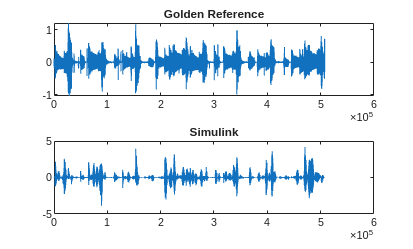

%% claming the length for compare
N = min(length(audio_out_gd), length(audio_out_sl));
audio_gd_cmp = audio_out_gd(1:N);
audio_sl_cmp = audio_out_sl(1:N);

%% Plot the results.
figure;
subplot(2,1,2); plot(audio_sl_cmp); title('Simulink');
subplot(2,1,1); plot(audio_gd_cmp); title('Golden Reference');


Maximum error for Golden Reference vs Simulink out of 507821 values
 3.501835e+00 (absolute), 2.892731e+02 (percentage)


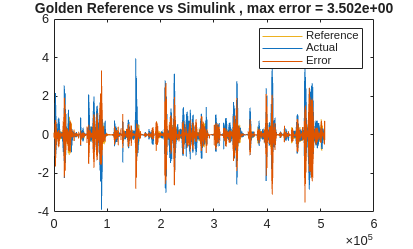


compareData(audio_gd_cmp,audio_sl_cmp,{2 1 1},'Golden Reference vs Simulink');

## Audio for DUT

% 저장/재생
audio_out_sl = double(audio_out_sl);
soundsc(audio_out_sl, fs_audio);